% this function returns how many iterations it takes for a point to diverge
% if a point converges, the function will output 100
function it = fractal(c)
    it = 0;
    z = 0+0i;
    while (abs(z)<=2 && it<100)
        z = z^2 + c;
        it = it + 1;
    end
end

% this function returns an indicator function along a vertical line at a given x
function fn = indicator_fn_at_x(x)
  % it uses equivalence of logical variables (true - 1, false - 0)
  % to produce a value of 1 for divergence and -1 for no divergence
  fn = @(y) (fractal(x + 1i * y) < 100) * 2 - 1; 
end

% this function finds the point on the boundary of the fractal
% by using the bisection method

function m = bisection(fn_f, s, e)
    m = (s + e) / 2; % Calculate the midpoint
    if abs(s-e) > 0.001
        if fn_f(m) == 1 % Check if the midpoint indicates divergence
            m = bisection(fn_f, s, m); % Move the end to the midpoint
        else
            m = bisection(fn_f, m, e); % Move the start to the midpoint
        end
    end
end


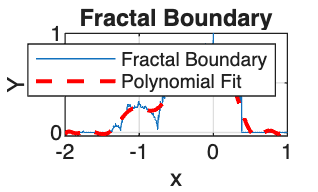

% Finds the fractal boundary for x ∈ [−2, 1] for at least 10^3 points.
xValues = linspace(-2, 1, 1000); % Generate 1000 points between -2 and 1
boundary = arrayfun(@(x) bisection(indicator_fn_at_x(x), 0, 2), xValues); % Find the boundary for each x

% Plot the fractal boundary
plot(xValues, boundary);
xlabel('x');
ylabel('Y');
title('Fractal Boundary');
grid on;

% fit a polynomial of degree 15 to the approximated boundary points
p = polyfit(xValues, boundary, 15);

% Evaluate the polynomial at specific points for visualization
xFit = linspace(-2, 1, 100);
yFit = polyval(p, xFit);
% Plot the polynomial fit for visualization
hold on; 
plot(xFit, yFit, 'r--', 'LineWidth', 1.5);
legend('Fractal Boundary', 'Polynomial Fit');
hold off; 


% this function computes the curve length of a polynomial
function l = poly_len(p,s,e)
    % derivative coefficients of p
    dp = polyder(p);
    % anonymous function ds
    ds = @(x) sqrt(1 + (polyval(dp, x)).^2);
    
    l = integral(ds, s, e);
end

% Finds the curve length of the polynomial fitted to the boundary
% of the Mandelbrot set
l = poly_len(p,-1.4,0.38)

l = 2.3730